Pirmais mājasdarbs

Patriks Raiss-Reiss Adaptronika 3. kurss 231REC051

Variants: 753

Basic scenario/map setup

clear all;

scenario = robotScenario(UpdateRate=5);

floorColor = [1 0 0.5];
addMesh(scenario, "Plane", Position=[4.5 2.5 0], Size=[9 5], Color=floorColor);

wallHeight = 1;
wallWidth = 0.05;
wallColor = [1 1 0.8157];

Add outer walls to the map

addMesh(scenario, "Box", Position=[0+wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 5-wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[9-wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 0+wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Add inner walls to the map

addMesh(scenario, "Box", Position=[1, 2, wallHeight/2], ...
    Size=[2, 4, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4, 1.5, wallHeight/2], ...
    Size=[2, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6, 3.5, wallHeight/2], ...
    Size=[4, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6.5, 2, wallHeight/2], ...
    Size=[1, 2, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[7.5, 1.5, wallHeight/2], ...
    Size=[1, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Visualize the map

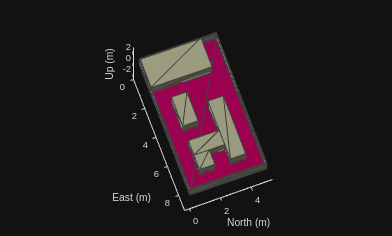

show3D(scenario);
lightangle(-45, 30);
view(70, 70);

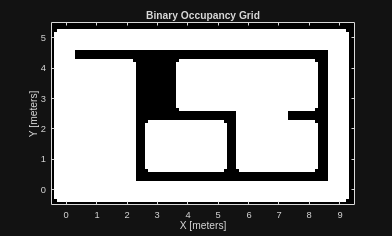


map = binaryOccupancyMap(scenario, GridOriginInLocal=[-0.5 -0.5], MapSize=[10 6], MapHeightLimits=[0 3]);
inflate(map, 0.25);
show(map);

Define map points

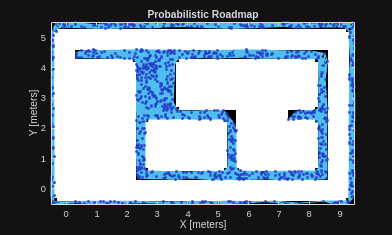

startPosition = [0.5 4.5];
goalPosition = [8.5 0.5];

rng(100);

numnodes = 1000;
planner = mobileRobotPRM(map, numnodes);
planner.ConnectionDistance = 1;

show(planner);


waypoints = findpath(planner, startPosition, goalPosition);

Define and setup te robot

robotHeight = 0.12;

numWaypoints = size(waypoints, 1);

firstInTime = 0;

lastInTime = firstInTime + (numWaypoints - 1);
traj = waypointTrajectory(SampleRate=10, TimeOfArrival=firstInTime:lastInTime, ...
    Waypoints=[waypoints, robotHeight * ones(numWaypoints, 1)], ...
    ReferenceFrame="ENU");

huskyRobot = loadrobot("clearpathJackal");

platform = robotPlatform("husky", scenario, RigidBodyTree=huskyRobot, BaseTrajectory=traj);

Visualization of the robot path

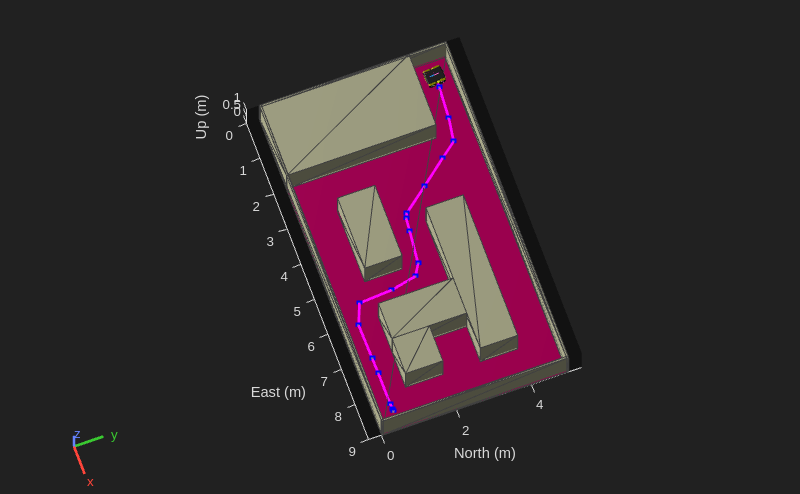

[ax, plotFrames] = show3D(scenario);
lightangle(-45, 30);
view(70, 70);

hold(ax, "on");
plot(ax, waypoints(:,1), waypoints(:, 2), "-ms", LineWidth=2, MarkerSize=4, ...
    MarkerEdgeColor="b", MarkerFaceColor=[0.5 0.5 0.5]);
hold(ax, "off");

Simulation setup and robot movement

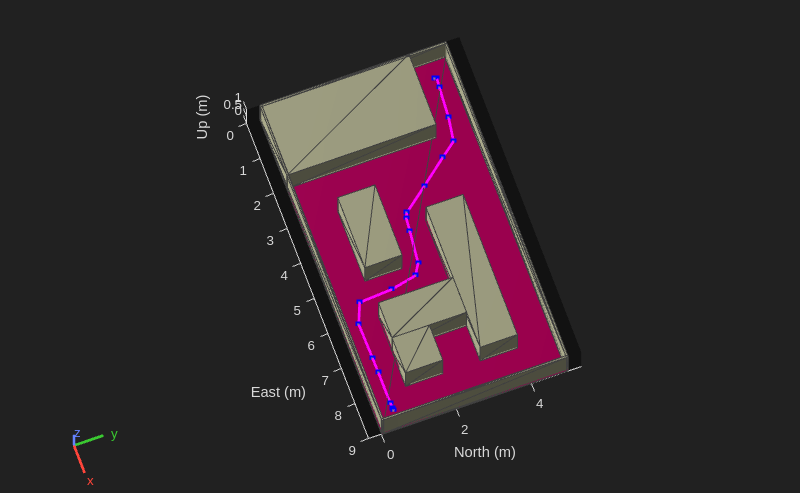

setup(scenario);

r = rateControl(20);

robotStartMoving = false;

while advance(scenario)
    show3D(scenario, Parent=ax, FastUpdate=true);
    waitfor(r);

    currentPose = read(platform);

    if ~any(isnan(currentPose))
        robotStartMoving = true;
    end

    if any(isnan(currentPose)) && robotStartMoving
        break;
    end
end